# M3DYN1 – 3 timer skriftlig eksamen august 2020 (Alle hjælpemidler tilladt) 

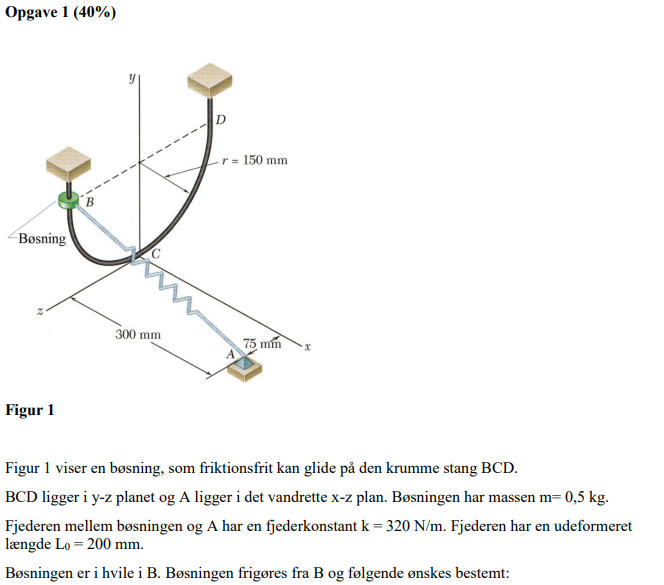

#### **Underopgave 1.A** - Vis at fjederens totale længde LAC, mellem A og C, er lig med 309,23 mm og  fjederens totale længde LAB, mellem A og B, er lig med 343,69 mm:

Vi kan finde LAC, ved at kigge på det som en trekant oppe fra og anvende pytagoras's læresætning til at udregne LAC:

LAC = sqrt(300^2 + 75^2)

LAC = 309.2329

Da radius på halvcirklen er oplyst, så er det kendt, at y-afstanden CB er 150 mm. Heraf anvendes LAC som x-afstanden.. 

Igen anvendes pytagoras til at udregne LAB:

LAC = sqrt(309.2329^2 + 150^2)

LAC = 343.6932

#### 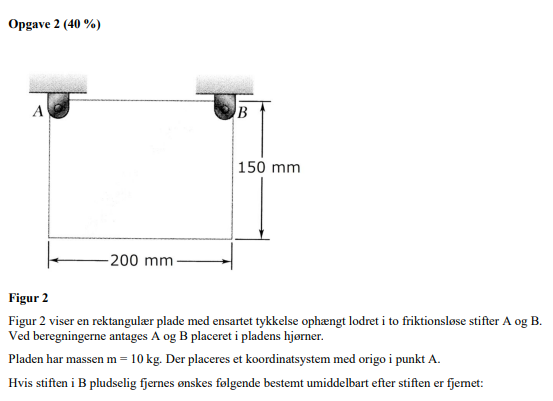

Informationer:

- Pladens masse, $m_p = 10 kg$

- Tyngeaccelerationen, $g = 9.81 \frac{m}{s^2}$

#### **Underopgave 2.A** - Optegn FBD & KD af pladen:

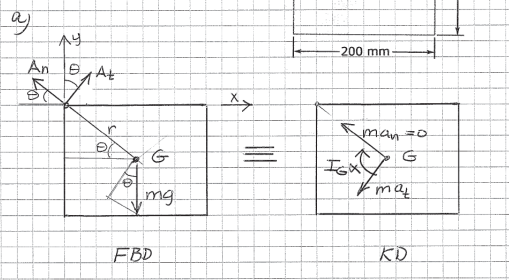

**Underopgave 2.B** - **Bestem pladens masseinertimoment om tyngdepunktet IG:**

Fra Properties of Homogeneous Solids Tabel D/4, Rektangulær Parallelepiped

har vi at $I_{yy} = \frac{1}{12}m \cdot (b^2 + l^2) = I_G \\
\rightarrow \\
I_G = \frac{1}{12} \cdot 10 kg \cdot ((150 mm)^2 + (200 mm)^2) \\ \rightarrow \\ I_G = 0.052083 kg \cdot m^2$

b = 0.15;
l = 0.200;

m = 10;

I_G = vpa((1/12)*m*((b)^2 + (l)^2),5);

**Underopgave 2.C** **- Bestem pladens masseinertimoment IA om punkt A**

Når man ønsker at finde masseinertimomentet om et punkt, så skal man først kende masseinertimomentet for centrum.

Når det er kendt, så kan man ved massen gange flytningen i anden til punktet finde masseinertimomentet om det punkt.

Vi ved fra forhenværende opgave 2.B, at vores centrumsmasseinertimoment er: $I_G$.

Afstanden til punktet a fra centroiden kan findes ved pythagoras:

Afstand fra center til A: $b = \sqrt{(b/2)^2 + (l/2)^2}$

m = 10;
r = sqrt((b/2)^2 + (l/2)^2);
I_A = I_G + m*r^2

$$I\_A = 0.20833333333333570180911920033395$$

#### 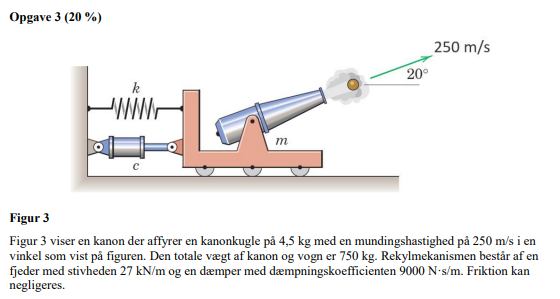

Informationer:

- Masse af enhed, $m = 750 kg$

- Masse kanonkugle, $m_{k} = 4.5 kg$

- Affyringshastigheden, $v_k = cos(20\degree ) \cdot 250 \frac{m}{s^2}$

- Fjederstivheden, $k = 27 \frac{kN}{m} \rightarrow 27000 \frac{N}{m}$

- Dæmpningskoefficienten, $c = 9000 \frac{N \cdot s}{m}$

- Den naturlige frekvens: $\omega_n = \sqrt{\frac{k}{m}} = 6
$

- Dæmpning raten: $\zeta = \frac{c}{2 \cdot m \cdot \omega_n} = 1$

### ***Underopgave 1.A: ****Bestem kanonens vandrette hastighed lige efter affyring. Anvend bevarelse af lineær momentum. *

Da vi har to påvirkende faktorer:

- Kanon der affyrer.

- Kanonkuglen der affyres.

Så har vi to komposenter i den vandrette retning.

Vi kan herfra anvende ligningen for det lineære momentum:

- 
$$\Delta G = v_k \cdot m_k = m \cdot v_{kanon} \rightarrow v_{kanon} = \frac{v_k \cdot m_k}{m} \\ v_{kanon} = 1.40954 \frac{m}{s}$$


m_k = 4.5;
m = 750;
v_0 = 250;
theta = 20;
v_kugle = v_0*cosd(theta); 

v_kanon = vpa((v_kugle*m_k)/m,6);

### ***Underopgave 1.B: ****Bestem systemets cykliske egenfrekvens og dæmpningsforholdet.*

Egenfrekvensen af kanonen er angivet som:

- 
$$\omega_n = \sqrt{\frac{k}{m}} =  \frac{Rad}{sec} \\ \rightarrow \\ \sqrt{\frac{27000\frac{N}{m}}{750kg}} = 6 \frac{Rad}{sec}
$$


Dæmpningsforholdet er angivet udfra zeta.

Hvis zeta angiver en værdi:

- under 1, så er systemet under dæmpet.

- ligmed 1, er systemet kritisk dæmpet.

- over 1, er systemet over dæmpet.

Zeta er givet som:

-  
$$\zeta = \frac{c}{2 \cdot m \cdot \omega_n} \\ \rightarrow \\  \frac{9000}{2 \cdot 750 \cdot 6} = 1$$


Ergo, vores system er **Kritisk dæmpet.**

m = 750;
k = 27000;
c = 9000;

omega_n = sqrt(k/m);
zeta_brug = 0;
zeta = c/(2*m*omega_n);
if zeta < 1
    zeta_brug = zeta
    display("SYSTEMET ER UNDER DÆMPET!");
elseif zeta == 1
    zeta_brug = zeta
    display("SYSTEMET ER KRITISK DÆMPET!");
elseif zeta > 1
    zeta_brug = zeta
    display("SYSTEMET ER OVER DÆMPET!");
end

zeta_brug = 1

    "SYSTEMET ER KRITISK DÆMPET!"



### ***Underopgave 1.C: ****Bestem kanonens største vandrette flytning*